# Does V1 response suppression initiate binocular rivalry?

Welcome to the controller live-script for figure generation of the BRFS manuscript as submitted to iScience.

As Cell Press authors, we share all of the data and original code we report in our paper with the research community. This live-script plots the figures reported in the associated manuscript at iScience. The data have been published on Zenodo: 

#### Carlson, Brock, M., Mitchell, Blake, A., Kacie Dougherty, Westerberg, Jacob, A., & Maier, Alexander. (2023). Does V1 response suppression initiate binocular rivalry?. Iscience. https://doi.org/10.5281/zenodo.7951315

This script is dependent on Gramm which can be found at https://github.com/piermorel/gramm

This notebook processes our event-locked data, uses Gramm to plot continuous data, and then formats datastructures of subsequent stastical analysis in JASP.

## Step 1: Download the data from Zenodo

There is not a programatic integration between Zenodo and MATLAB. You may manually download the data via the following steps:

- Navigate to this publications data directory:  [https://doi.org/10.5281/zenodo.7949494](https://doi.org/10.5281/zenodo.7949494)

- Create a data folder to be accesed by this script such as: C:\ ... \MATLAB\BMC_AdaptdcosFigures

- Download all data to this directory. Total file size is 4.0GB.

## Step 2: Set up root directory

This should be the folder you established in the last step with the data from Zenodo. Processed data structures and  will also be saved to this folder.

ROOTDIR = 'C:\Users\neuropixel\Documents\MATLAB\BMC_AdaptdcosFigures\';
cd(ROOTDIR)

## Step 3: Individual unit classification

To obtain multiunit activity (MUA) from the broadband signal, we low-pass filtered the 30kHz-sampled voltage signals at 5 kHz with a bidirectional Butterworth filter. We then down sampled by a factor of 3, followed by application of a second-order bidirectional Butterworth filter to high-pass filter at 1kHz. We then rectified the resulting data, and down sampled by another factor of 3. To detect impulses (spikes) in the MUA signal, a time-varying threshold enveloped the broadband signal. An impulse was recorded whenever the signal exceeded a pre-set threshold of 2.2 times the noise floor. The threshold was computed after smoothing the signal. Signal smoothing was achieved by convolving the data with a 12s boxcar. 

The MUA signal is triggered to each photo diode onset of a successful trial. Metadata and triggered continuous data are contained in the STIM structure for each file's sesion. We can now organize the data in a condition-specific format and evaluate each multi-units individual tuning characteristics (namely ocular dominance and orientaiton preference).

%% Individual Unit Classification
[IDX,ERR] = IDX_iScienceSubmission(ROOTDIR)

151221_E_eD/ / contact =_1


151221_E_eD/ / contact =_2


151221_E_eD/ / contact =_3


151221_E_eD/ / contact =_4


151221_E_eD/ / contact =_5


151221_E_eD/ / contact =_6


151221_E_eD/ / contact =_7


151221_E_eD/ / contact =_8


151221_E_eD/ / contact =_9


151221_E_eD/ / contact =_10


151221_E_eD/ / contact =_11


151221_E_eD/ / contact =_12


151221_E_eD/ / contact =_13


151221_E_eD/ / contact =_14


151221_E_eD/ / contact =_15


151221_E_eD/ / contact =_16


151221_E_eD/ / contact =_17


151222_E_eD/ / contact =_1


151222_E_eD/ / contact =_2


151222_E_eD/ / contact =_3


151222_E_eD/ / contact =_4


151222_E_eD/ / contact =_5


151222_E_eD/ / contact =_6


151222_E_eD/ / contact =_7


151222_E_eD/ / contact =_8


151222_E_eD/ / contact =_9


151222_E_eD/ / contact =_10


151222_E_eD/ / contact =_11


151222_E_eD/ / contact =_12


151222_E_eD/ / contact =_13


151222_E_eD/ / contact =_14


151222_E_eD/ / contact =_15


151222_E_eD/ / contact =_16


151222_E_eD/ / contact =_17


151222_E_eD/ / contact =_18


151222_E_eD/ / contact =_19


151231_E_eD/ / contact =_1


151231_E_eD/ / contact =_2


151231_E_eD/ / contact =_3


151231_E_eD/ / contact =_4


151231_E_eD/ / contact =_5


151231_E_eD/ / contact =_6


151231_E_eD/ / contact =_7


151231_E_eD/ / contact =_8


151231_E_eD/ / contact =_9


151231_E_eD/ / contact =_10


151231_E_eD/ / contact =_11


160102_E_eD/ / contact =_1


160102_E_eD/ / contact =_2


160102_E_eD/ / contact =_3


160102_E_eD/ / contact =_4


160102_E_eD/ / contact =_5


160102_E_eD/ / contact =_6


160102_E_eD/ / contact =_7


160102_E_eD/ / contact =_8


160102_E_eD/ / contact =_9


160102_E_eD/ / contact =_10


160102_E_eD/ / contact =_11


160102_E_eD/ / contact =_12


160102_E_eD/ / contact =_13


160102_E_eD/ / contact =_14


160102_E_eD/ / contact =_15


160104_E_eD/ / contact =_1
160104_E_eD/ / contact =_2


160104_E_eD/ / contact =_3
160104_E_eD/ / contact =_4
160104_E_eD/ / contact =_5
160104_E_eD/ / contact =_6


160104_E_eD/ / contact =_7


160104_E_eD/ / contact =_8
160104_E_eD/ / contact =_9
160104_E_eD/ / contact =_10
160104_E_eD/ / contact =_11
160104_E_eD/ / contact =_12


160104_E_eD/ / contact =_13


160108_E_eD/ / contact =_1


160108_E_eD/ / contact =_2


160108_E_eD/ / contact =_3
160108_E_eD/ / contact =_4


160108_E_eD/ / contact =_5
160108_E_eD/ / contact =_6
160108_E_eD/ / contact =_7
160108_E_eD/ / contact =_8
160108_E_eD/ / contact =_9
160108_E_eD/ / contact =_10
160108_E_eD/ / contact =_11
160108_E_eD/ / contact =_12


160111_E_eD/ / contact =_1


160111_E_eD/ / contact =_2
160111_E_eD/ / contact =_3
160111_E_eD/ / contact =_4


160111_E_eD/ / contact =_5
160111_E_eD/ / contact =_6
160111_E_eD/ / contact =_7


160111_E_eD/ / contact =_8


160111_E_eD/ / contact =_9
160111_E_eD/ / contact =_10
160111_E_eD/ / contact =_11


160111_E_eD/ / contact =_12


160111_E_eD/ / contact =_13


160130_I_eD/ / contact =_1


160130_I_eD/ / contact =_2


160130_I_eD/ / contact =_3


160130_I_eD/ / contact =_4
160130_I_eD/ / contact =_5
160130_I_eD/ / contact =_6


160130_I_eD/ / contact =_7


160130_I_eD/ / contact =_8
160130_I_eD/ / contact =_9


160130_I_eD/ / contact =_10


160130_I_eD/ / contact =_11


160131_I_eD/ / contact =_1


160131_I_eD/ / contact =_2
160131_I_eD/ / contact =_3
160131_I_eD/ / contact =_4


160131_I_eD/ / contact =_5


160131_I_eD/ / contact =_6


160131_I_eD/ / contact =_7


160131_I_eD/ / contact =_8


160131_I_eD/ / contact =_9


160131_I_eD/ / contact =_10


160204_I_eD/ / contact =_1


160204_I_eD/ / contact =_2


160204_I_eD/ / contact =_3


160204_I_eD/ / contact =_4


160204_I_eD/ / contact =_5


160204_I_eD/ / contact =_6


160204_I_eD/ / contact =_7


160204_I_eD/ / contact =_8


160204_I_eD/ / contact =_9


160204_I_eD/ / contact =_10


160204_I_eD/ / contact =_11


160211_I_eD/ / contact =_1


160211_I_eD/ / contact =_2


160211_I_eD/ / contact =_3
160211_I_eD/ / contact =_4
160211_I_eD/ / contact =_5
160211_I_eD/ / contact =_6
160211_I_eD/ / contact =_7
160211_I_eD/ / contact =_8
160211_I_eD/ / contact =_9


160211_I_eD/ / contact =_10
160211_I_eD/ / contact =_11
160211_I_eD/ / contact =_12


160211_I_eD/ / contact =_13


160211_I_eD/ / contact =_14


160212_I_eD/ / contact =_1


160212_I_eD/ / contact =_2


160212_I_eD/ / contact =_3


160212_I_eD/ / contact =_4


160212_I_eD/ / contact =_5


160212_I_eD/ / contact =_6
160212_I_eD/ / contact =_7


160212_I_eD/ / contact =_8


160212_I_eD/ / contact =_9


160212_I_eD/ / contact =_10
160212_I_eD/ / contact =_11
160212_I_eD/ / contact =_12


160212_I_eD/ / contact =_13


160212_I_eD/ / contact =_14
160212_I_eD/ / contact =_15


160212_I_eD/ / contact =_16


160215_I_eD/ / contact =_1


160215_I_eD/ / contact =_2
160215_I_eD/ / contact =_3


160215_I_eD/ / contact =_4


160215_I_eD/ / contact =_5


160215_I_eD/ / contact =_6


160215_I_eD/ / contact =_7
160215_I_eD/ / contact =_8


160215_I_eD/ / contact =_9


160215_I_eD/ / contact =_10


160215_I_eD/ / contact =_11


160215_I_eD/ / contact =_12


160215_I_eD/ / contact =_13


160215_I_eD/ / contact =_14


160215_I_eD/ / contact =_15


160427_E_eD/ / contact =_1
160427_E_eD/ / contact =_2
160427_E_eD/ / contact =_3
160427_E_eD/ / contact =_4
160427_E_eD/ / contact =_5
160427_E_eD/ / contact =_6
160427_E_eD/ / contact =_7
160427_E_eD/ / contact =_8
160427_E_eD/ / contact =_9


160427_E_eD/ / contact =_10
160427_E_eD/ / contact =_11
160427_E_eD/ / contact =_12


160427_E_eD/ / contact =_13


160427_E_eD/ / contact =_14


160427_E_eD/ / contact =_15


160427_E_eD/ / contact =_16


160427_E_eD/ / contact =_17


160510_E_eD/ / contact =_1


160510_E_eD/ / contact =_2


160510_E_eD/ / contact =_3
160510_E_eD/ / contact =_4
160510_E_eD/ / contact =_5
160510_E_eD/ / contact =_6
160510_E_eD/ / contact =_7
160510_E_eD/ / contact =_8


160510_E_eD/ / contact =_9
160510_E_eD/ / contact =_10


160510_E_eD/ / contact =_11


160510_E_eD/ / contact =_12


160510_E_eD/ / contact =_13
160510_E_eD/ / contact =_14


160523_E_eD/ / contact =_1


160523_E_eD/ / contact =_2


160523_E_eD/ / contact =_3
160523_E_eD/ / contact =_4
160523_E_eD/ / contact =_5


160523_E_eD/ / contact =_6
160523_E_eD/ / contact =_7


160523_E_eD/ / contact =_8
160523_E_eD/ / contact =_9
160523_E_eD/ / contact =_10
160523_E_eD/ / contact =_11


160523_E_eD/ / contact =_12


160523_E_eD/ / contact =_13


160523_E_eD/ / contact =_14


161005_E_eB/ / contact =_1
161005_E_eB/ / contact =_2


161005_E_eB/ / contact =_3


161005_E_eB/ / contact =_4


161005_E_eB/ / contact =_5


161005_E_eB/ / contact =_6


161005_E_eB/ / contact =_7


161005_E_eB/ / contact =_8


161005_E_eB/ / contact =_9


161005_E_eB/ / contact =_10


161005_E_eB/ / contact =_11
161005_E_eB/ / contact =_12
161005_E_eB/ / contact =_13


161005_E_eB/ / contact =_14


161005_E_eB/ / contact =_15
161005_E_eB/ / contact =_16


161005_E_eB/ / contact =_17


161005_E_eB/ / contact =_18


161005_E_eD/ / contact =_1


161005_E_eD/ / contact =_2


161005_E_eD/ / contact =_3
161005_E_eD/ / contact =_4
161005_E_eD/ / contact =_5


161005_E_eD/ / contact =_6


161005_E_eD/ / contact =_7


161005_E_eD/ / contact =_8
161005_E_eD/ / contact =_9
161005_E_eD/ / contact =_10
161005_E_eD/ / contact =_11
161005_E_eD/ / contact =_12


161005_E_eD/ / contact =_13
161005_E_eD/ / contact =_14
161005_E_eD/ / contact =_15


161005_E_eD/ / contact =_16


161005_E_eD/ / contact =_17


161005_E_eD/ / contact =_18


161005_E_eD/ / contact =_19


161005_E_eD/ / contact =_20


161005_E_eD/ / contact =_21


161007_E_eB/ / contact =_1


161007_E_eB/ / contact =_2
161007_E_eB/ / contact =_3
161007_E_eB/ / contact =_4
161007_E_eB/ / contact =_5
161007_E_eB/ / contact =_6
161007_E_eB/ / contact =_7
161007_E_eB/ / contact =_8
161007_E_eB/ / contact =_9
161007_E_eB/ / contact =_10
161007_E_eB/ / contact =_11
161007_E_eB/ / contact =_12


161007_E_eB/ / contact =_13


161007_E_eB/ / contact =_14
161007_E_eB/ / contact =_15
161007_E_eB/ / contact =_16
161007_E_eB/ / contact =_17
161007_E_eB/ / contact =_18
161007_E_eB/ / contact =_19


161007_E_eB/ / contact =_20


IDX = struct with fields:
       Supra: [1×33 struct]
       allV1: [1×91 struct]
    Granular: [1×49 struct]
       Infra: [1×9 struct]


ERR = 1×190 struct array with fields:
    reason
    penetration
    depthFromSinkBtm


## Step 4: Plot data using [Gramm](https://github.com/piermorel/gramm)

To obtain multiunit activity (MUA) from the broadband sign


cd(ROOTDIR)
load(strcat(ROOTDIR,filesep,'IDX_iScienceSubmission.mat'))



Now we create images with Gramm.

ans =   1×2 gramm array with properties:

    legend_axe_handle
    title_axe_handle
    facet_axes_handles
    results


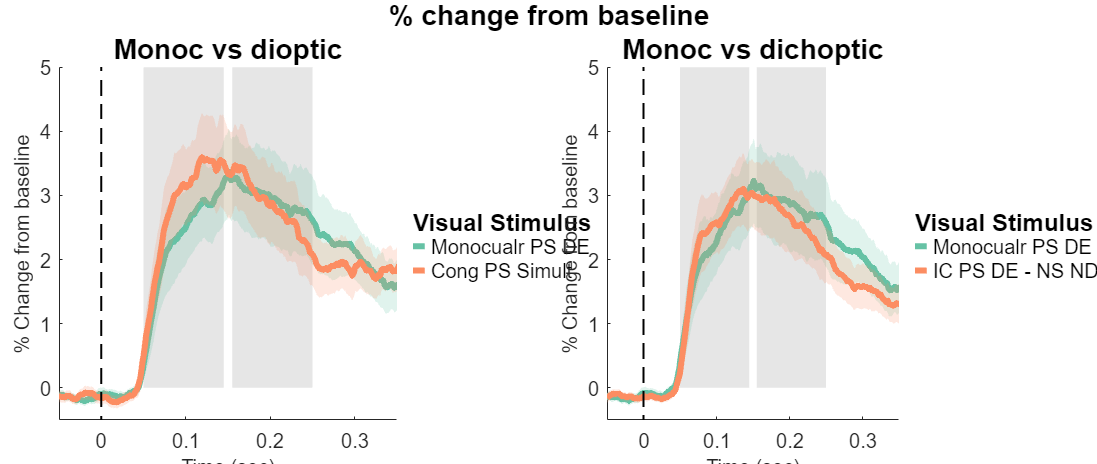

% IDX breakdown
numUnits = idxBreakdown(IDX,ERR);

%% Figure 2a and 2b
gramm_dCOS_line(IDX);

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: []


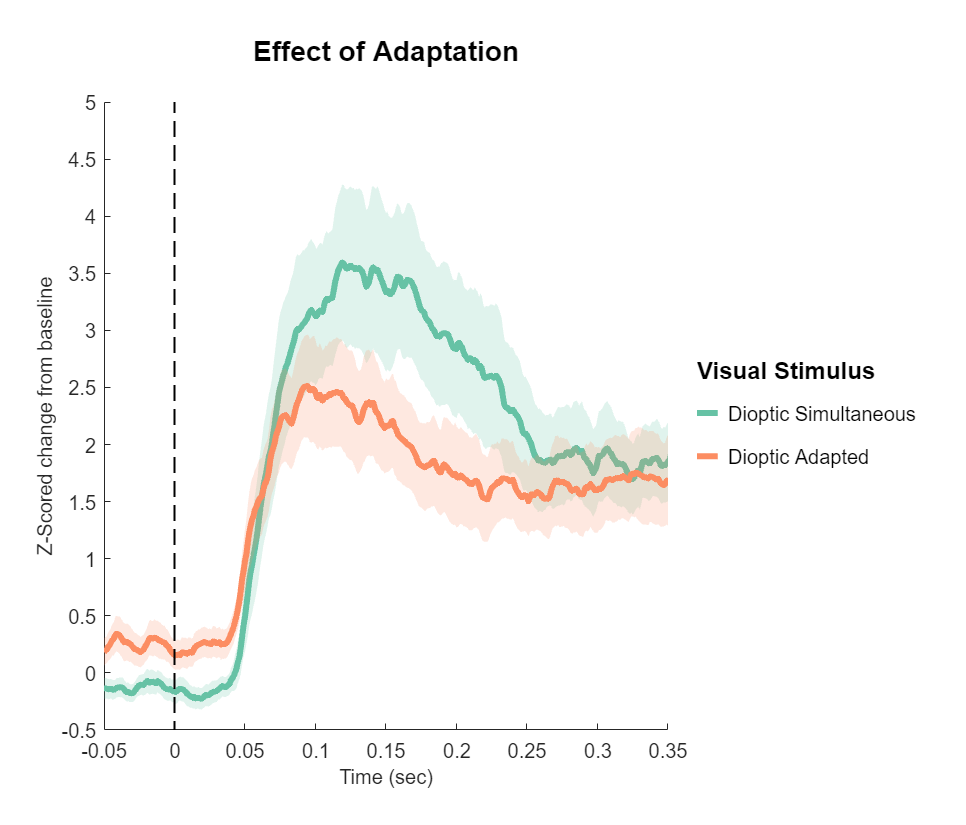


% Figure 2c
gramm_adaptation_line(IDX)

ans =   1×2 gramm array with properties:

    legend_axe_handle
    title_axe_handle
    facet_axes_handles
    results


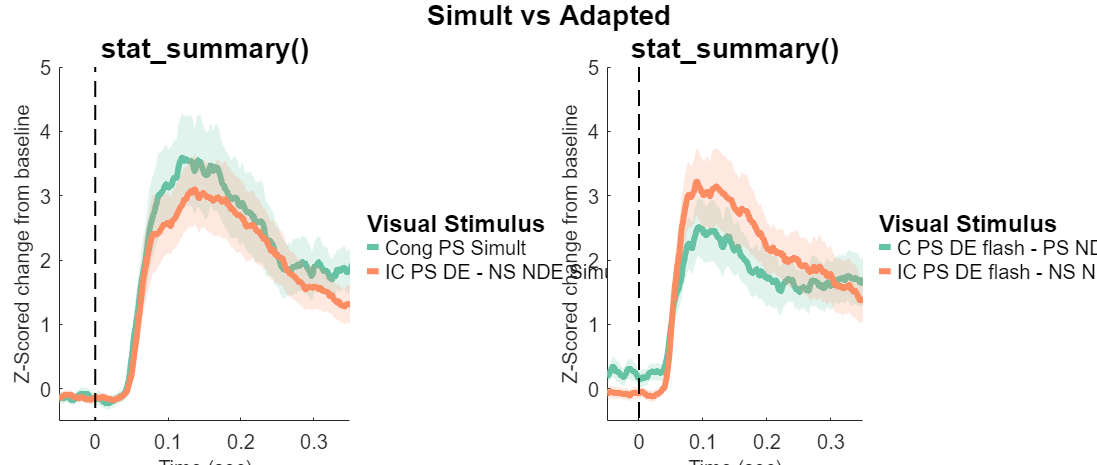


% Figure 3
gramm_2x2_line(IDX)

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: []


ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


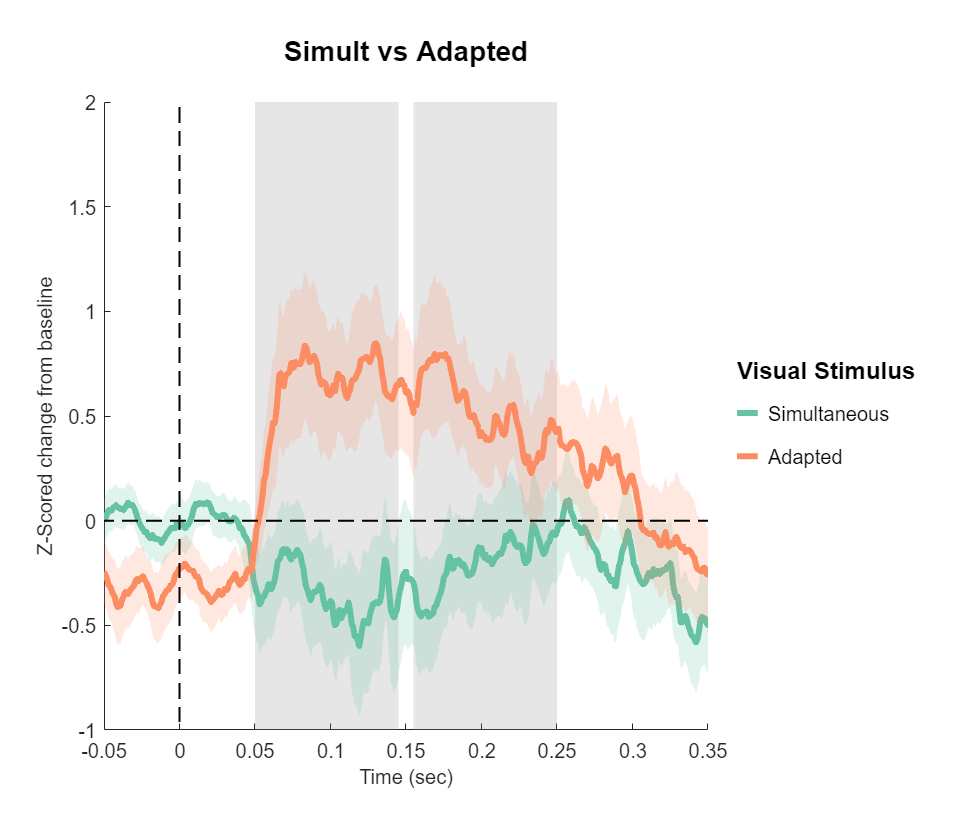

gramm_2x2_subline(IDX)

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


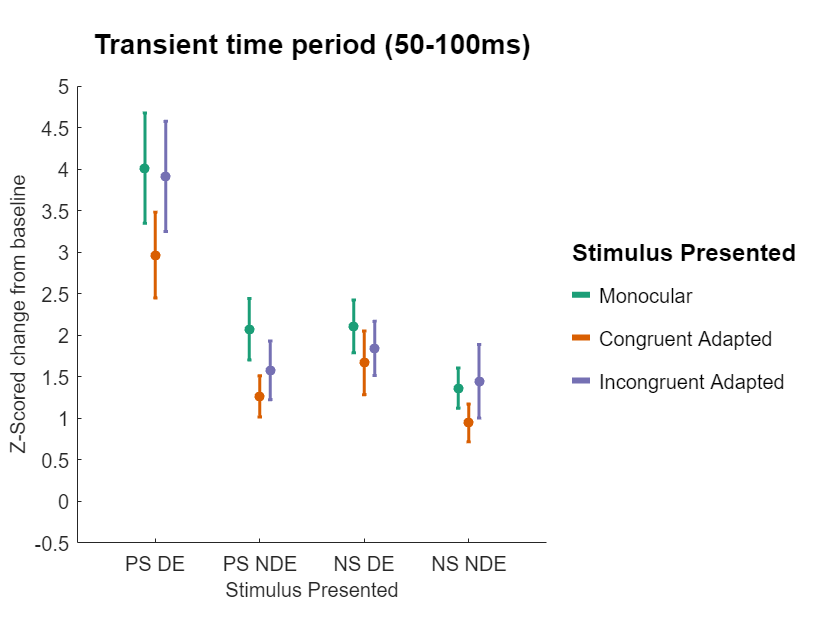


% Figure 4
gramm_adaptationEffect(IDX)

## Step 2: format data for JASP

Next we format the IDX output into a .csv that JASP can accept

Because we are running a repeated measures t-tests and a repeated measures ANOVA, the results must be formateed (A x B) where A is each unit and B are the various conditions possible. The contents of each cell is the average response (within a given time-window) for a given unit to all presentations of that column's condition. Note that there will be missing conditions for each unit because not all conditions were shown on any individual day. Furthermore, while the condition shown to the subjects were selected for the majority of unit preferences on any given day, there are frequently a few units tuned to the ipsilateral eye and orthagonal orientation. Because preferences are established from the unit's perspective, some units will not have the prefered stimulus shown to the dominant eye. JASP does a good job of tracking and correcting for missing values. You can select to ignore missing values listwise or conditionwise. Typically, it is best practice to ignore missing values listwise to keep the degrees of freedomn identical between contrasts.

%% JASP conversion
% JASP requires each unit to be in a row vector with each column as the
% different conditions.
% Currently each row of IDX.allV1 is for its own unit (that's good).
% IDX.allV1.RESP_avg contains a 24x1 cell, where each cell contains the
% average for all 4 time periods of the RESP vector. 
% We have 24 potential conditions
% The output required are 88 x 24 arrays.
% We need 1 array for the transient period and 1 array for the sustained.
% win_ms is [transient, sustained, whole time, baseline]

numberOfUnits = size(IDX.allV1,2);

for i = 1:numberOfUnits
    for j = 1:24
        outputForJASP_transient(i,j) = IDX.allV1(i).RESP_avg{j}(1);
        outputForJASP_sustained(i,j) = IDX.allV1(i).RESP_avg{j}(2);
    end
end

%% Writetable
% Now we need to export these values to .csv for JASP import. It would be
% great if I did not have to input 24 condition labels by hand

conditionLabels = IDX.allV1(1).condition;
conditionNames = conditionLabels.Properties.RowNames;
outputForJASP_transient_table = array2table(outputForJASP_transient);
outputForJASP_sustained_table = array2table(outputForJASP_sustained);

outputForJASP_transient_table.Properties.VariableNames = conditionNames;
outputForJASP_sustained_table.Properties.VariableNames = conditionNames;

cd(ROOTDIR)
    saveNameTrans = strcat('JASP_transient','.csv');
    saveNameSus     = strcat('JASP_sustained','.csv');
    writetable(outputForJASP_transient_table,saveNameTrans)
    writetable(outputForJASP_sustained_table,saveNameSus)